### Quaternion Averaging 

[https://ntrs.nasa.gov/api/citations/20070017872/downloads/20070017872.pdf](https://ntrs.nasa.gov/api/citations/20070017872/downloads/20070017872.pdf)

clc;clear;close all
[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

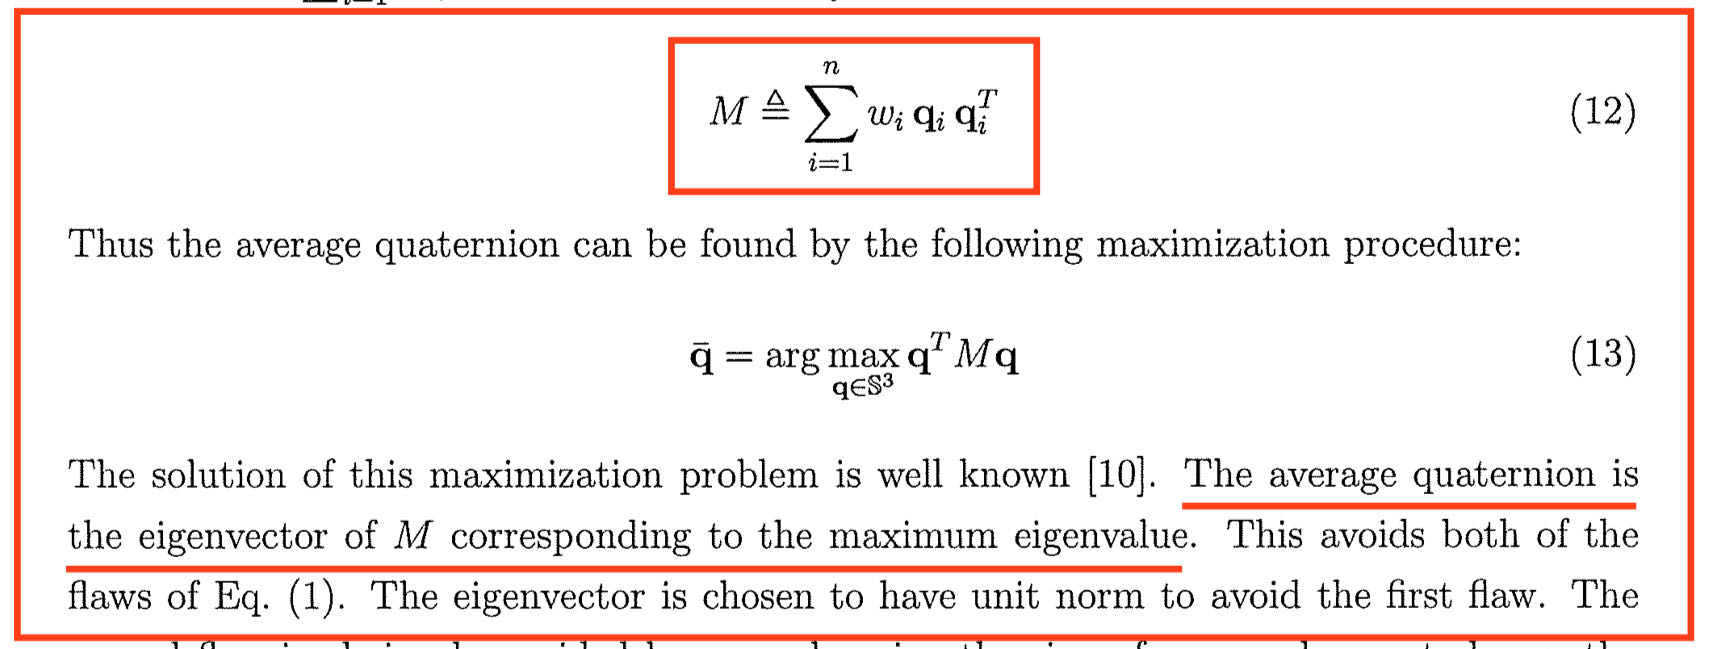

### Create Simulation Data

numpose = 9; % 9 set of data
dT = NaN(4,4,numpose);
T0 = randSE3(2*pi,20); % data without noise
for i = 1:numpose
    dT(:,:,i) = randSE3(10/180*pi,0.5); % add random noise，+-10deg，+-0.5m
end
T = pagemtimes(T0,dT); % 9 set of data with noise

w = [2,2,3,4,4,4,3,2,2]; % weight

### Find Weighted Average SE3

T_avg = AvgSE3(T(1:3,1:3,:),T(1:3,4,:),w); 

### Plot

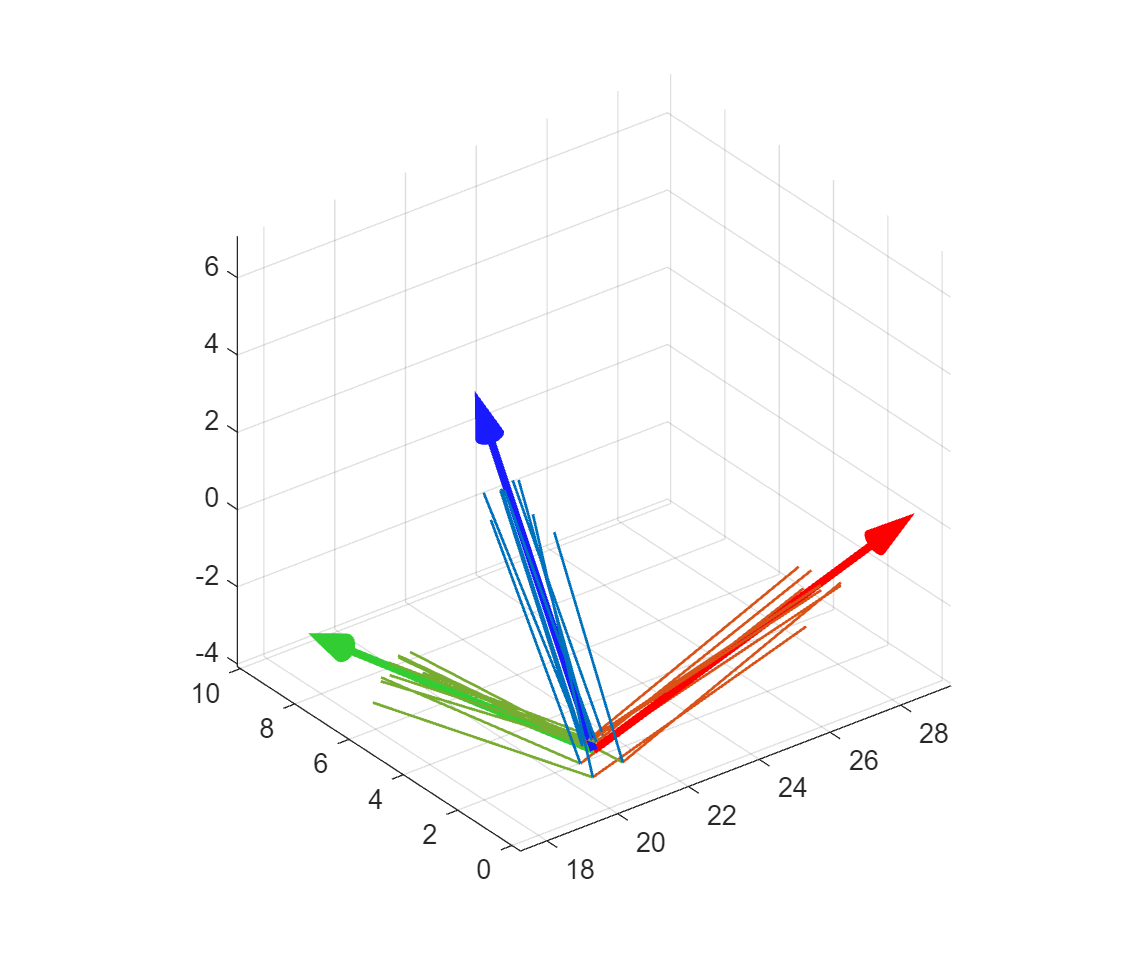

f = figure;
for i = 1:numpose
    PlotFrame(T(:,:,i),'scale',7,'linewidth',1,...
        'style','-','colorind',2,'text','off');hold on
end
PlotFrame(T_avg,'scale',10,'linewidth',3,'style','-',...
    'arrowsize',1/8,'colorind',1,'text','off');hold on
axis equal; grid on
set(f,'Units','normalized','Position',[0,0,0.6,0.8])